# DMD pattern Design

## dmd pattern generate

%% common params setting
dmd_size = 10; % dmd size
% dmd_size = 256; % dmd size
Cr = 10         % compressive ratio

Cr = 10

dmd_type = 'manual'

dmd_type = 'manual'

dmd_type:

'center_circle'

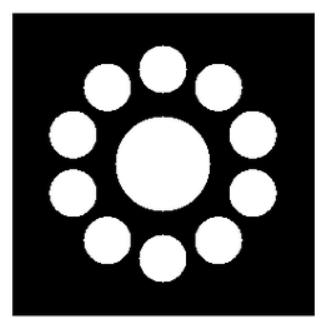

## dmd generate

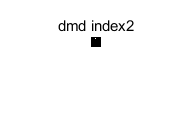

% [1] 'center_circle'
if strcmp(dmd_type, 'center_circle')
    % params
    center_circle_r = 20;
    out_cricle_r = 60;
    out_cricle_dist = 90; % distance between out circle and center circle
    
    % pre calc: cricle_position
    center_circle_p = round([dmd_size; dmd_size]./2);
    
    theta = 2*pi/Cr;
    roate_mtx = [cos(theta), sin(theta); -sin(theta), cos(theta)];
    out_circle_p = zeros(2, Cr);
    out_circle_p(:,1) = [dmd_size/2 - out_cricle_dist; dmd_size/2]; % first out circle
   
    for i = 2:Cr
        % pre out_circle's center coord (relative to dmd center)
        pre_circle_p = out_circle_p(:,i-1);
        pre_circle_p2center =  pre_circle_p - center_circle_p;
        cur_circle_p2center = roate_mtx*pre_circle_p2center;
        cur_circle_p = cur_circle_p2center + center_circle_p;
        out_circle_p(:,i) = cur_circle_p;
    end
    
    % generate dmd
    dmd = zeros([dmd_size dmd_size Cr]);
    for i = 1:Cr
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl(tmp_dmd, out_cricle_r,  out_circle_p(:,i));
        dmd(:,:,i) = tmp_dmd;
    end
         
    % show
    dmd_sum = sum(dmd,3);
    dmd_sum(dmd_sum>0)=1;
    imshow(dmd_sum);
    title('all dmd merged')

% [2] 'row_stripe' 
elseif strcmp(dmd_type, 'row_stripe')
    % params
    row_num = 10;
    row_value = eye(row_num,Cr);
    
    % generate
    dmd = zeros([dmd_size dmd_size Cr]);

    for k = 1:Cr
        init_dmd = repmat(row_value(:,k), 1, row_num);
        
        if row_num ~= dmd_size
            dmd_kron = kron(init_dmd, ones(floor(dmd_size/row_num)));
	    dmd(:,:,k) = imresize(dmd_kron, [dmd_size,dmd_size]);
        else
            dmd(:,:,k) = init_dmd;
        end
    end
    
    % show
    imshow(dmd(:,:,2));
    title('dmd index2')

% [2] 'seq_blank' 
elseif strcmp(dmd_type, 'seq_blank')
    % sequential single single subblank on
    
    % params
    dmd_blk_shape = [7 7];
    % dmd_blk_shape = ceil(sqrt(Cr))*ones(1,2);
    % dmd_on_ind = 1:10;
    dmd_on_ind = round(linspace(1,49,10));
    
    
    % generate
    dmd_size = [dmd_size dmd_size Cr];
    dmd = zeros(dmd_size);
    
    for k = 1:dmd_size(3)
        tmp = zeros(dmd_blk_shape);
        tmp(ind2sub(dmd_blk_shape, dmd_on_ind(k))) = 1;
        if dmd_blk_shape(1)  ~= dmd_size(1)
            dmd_kron = kron(tmp, ones(floor(dmd_size(1:2)./dmd_blk_shape)));
            dmd_k = imresize(dmd_kron, dmd_size(1:2),'Method','nearest');
        else
            dmd_k = tmp;            
        end
        dmd(:,:,k) = dmd_k;
    end
    
    % show
    imshow(dmd(:,:,2));
    title('dmd index2')    
    
    
% [4] 'rand_blank' 
elseif strcmp(dmd_type, 'multi_blank')
    % random fixed size subblanks
    % boundary of the left-up corner of subblanks
    
    % params
    dmd_subblank_size = [20 20];
    dmd_margin = 10;            % margin area can not be selected as square center
    % dmd_subblank_num = 1:10;    % for random pos mode
    dmd_subblank_num = 1*ones(10);
    
    % generate
    if isscalar(dmd_subblank_num)
        % the same blanks for each dmd
        dmd_subblank_num = dmd_subblank_num*ones(Cr);
    end
    dmd_size = [dmd_size dmd_size Cr];
    p_low = [dmd_margin dmd_margin];
    p_up = dmd_size(1:2) - dmd_subblank_size - dmd_margin;
    dmd = zeros(dmd_size);
    for k = 1:Cr
        % random left-up corner
        left_up_p = [randi([p_low(1), p_up(1)], [1 dmd_subblank_num(k)]);...
        randi([p_low(2), p_up(2)], [1 dmd_subblank_num(k)])];
        right_down_p = left_up_p + dmd_subblank_size'-1;
        tmp = zeros(dmd_size(1:2) );
        
        for m=1:dmd_subblank_num(k)
            tmp(left_up_p(1,m):right_down_p(1,m),left_up_p(2,m):right_down_p(2,m)) = 1;
        end
        
        dmd(:,:,k) = tmp;
    end    
    
    % show
    imshow(dmd(:,:,2));
    title('dmd index2')     
    
% [5] 'manual' 
elseif strcmp(dmd_type, 'manual')
    % manually design all the dmd
    
    % params
    dmd_blk_shape = [10 10]; % block shape
    % on block index for each dmd
    dmd_on_ind{1} = [2,2];
    dmd_on_ind{2} = [2,5];
    dmd_on_ind{3} = [3,3];
    dmd_on_ind{4} = [3,9];
    dmd_on_ind{5} = [5,2];
    dmd_on_ind{6} = [6,7];
    dmd_on_ind{7} = [8,5];
    dmd_on_ind{8} = [8,8];
    dmd_on_ind{9} = [9,3];
    dmd_on_ind{10} = [5,5];

    % generate
    dmd_size = [dmd_size dmd_size Cr];
    dmd = zeros(dmd_size);
    
    for k = 1:dmd_size(3)
        tmp = zeros(dmd_blk_shape);
        pos = dmd_on_ind{k};
        for m = 1:size(pos,1)
            pos_m = pos(m,:);
            tmp(pos_m(1),pos_m(2)) = 1;
        end
        if dmd_blk_shape(1)  ~= dmd_size(1) 
            dmd_kron = kron(tmp, ones(floor(dmd_size(1:2)./dmd_blk_shape)));
            dmd_k = imresize(dmd_kron, dmd_size(1:2),'Method','nearest');
        else
            dmd_k = tmp;
            
        end
        dmd(:,:,k) = dmd_k;
    end   
    
     % show
    imshow(dmd(:,:,2));
    title('dmd index2')     
end

## special pattern design

## save dmd

% saving_path = './designed_dmd/'
saving_path = 'E:\project\CACTI\simulation\config\dmd\designed_dmd\'

saving_path = 'E:\project\CACTI\simulation\config\dmd\designed_dmd\'

disp(datetime);

   2020-07-18 16:44:04


saving_name = [dmd_type '_dmd_' num2str(dmd_size(1)) '_' num2str(Cr) 'f.mat'];
save([saving_path saving_name], 'dmd');

## append functions

function z = cyl(N,R,P)
% CYL generates samples of a continuous, aperiodic, unity-height cylinder 
% at the points specified in P with radius R (percent of the length) on a background 
% rectangle with size N.
% 
%   Input:
%   --------
%   - N: 2-elements int vector, background rectangle size
%	- P: 2-elements int vector,centre point of the cylinder, default=[0,0]
%	- R: float scalar, radius of the cylinder
%   Output:
%   --------
%   - z: unity-height cylinder 

% input check
if numel(N)==1
	N = [N,N];		% background size
	z = zeros(N);	% background
elseif ~isvector(N)
	z = N;			% background
	N = size(z);	% background size
end

if nargin < 3
	P = round(N./2);
end

x0 = P(1);
y0 = P(2);
L1 = N(1);
L2 = N(2);

[x,y]=meshgrid(linspace(1, L1, L1), linspace(1, L2, L2)); 
x = x';
y = y';

r = sqrt((x-x0).*(x-x0)+(y-y0).*(y-y0)); % distance map

z(r<=R) = 1;
end